clear;clc;close
%% Dividing Data
L = readtable('PPDataSheet.xlsx') %loading table

L = 9568×5 table
     AT        V        AP       RH        PE  
    _____    _____    ______    _____    ______

     9.59    38.56      1017     60.1     481.3
    12.04    42.34    1019.7    94.67    465.36
    13.87    45.08    1024.4    81.69    465.48
    13.72     54.3    1017.9    79.08    467.05
    15.14    49.64    1023.8       75    463.58
    23.63    60.93    1006.4    83.06     439.9
    22.99    61.02    1009.9    81.56    440.85
    12.85       40    1015.9    68.85    463.74
    29.88    68.08    1011.1    55.78    429.33
    23.22    66.56    1002.5    85.39    437.11
     9.02    38.08      1019    69.98    478.32
    26.12     75.6    1017.4    72.31    439.68
    16.66    36.71    1013.7    70.66    466.07
    29.56    52.84    1006.1    42.17    436.46
       30     61.5    1009.4    48.63     43

T = L(7700:end,:) % Testing Set

T = 1869×5 table
     AT        V        AP       RH        PE  
    _____    _____    ______    _____    ______

    20.02    58.66    1011.5    76.74    454.21
    23.75    68.51    1013.2    76.01    441.61
     20.2     60.1    1010.7    84.24    451.17
    11.49    39.22    1016.4    53.11    471.47
    14.81    40.71    1018.5       73    467.66
    19.15    57.76    1019.6    74.89    458.66
     20.3    56.53    1020.3    76.49    454.12
     9.46     41.4    1026.8    87.58    480.82
    25.16     77.3    1000.7     86.4    439.37
    14.24    39.58    1011.2    70.45    469.94
    14.47    42.86    1031.5    66.73    466.64
     5.35    35.79    1013.2    93.53     483.2
     22.4    70.94    1008.1    84.52    440.04
    26.93    67.07    1005.6    60.26    437.76
    26.54    69.34    1009.5    87.18    435

W = L(1:end,:) % Working Set

W = 9568×5 table
     AT        V        AP       RH        PE  
    _____    _____    ______    _____    ______

     9.59    38.56      1017     60.1     481.3
    12.04    42.34    1019.7    94.67    465.36
    13.87    45.08    1024.4    81.69    465.48
    13.72     54.3    1017.9    79.08    467.05
    15.14    49.64    1023.8       75    463.58
    23.63    60.93    1006.4    83.06     439.9
    22.99    61.02    1009.9    81.56    440.85
    12.85       40    1015.9    68.85    463.74
    29.88    68.08    1011.1    55.78    429.33
    23.22    66.56    1002.5    85.39    437.11
     9.02    38.08      1019    69.98    478.32
    26.12     75.6    1017.4    72.31    439.68
    16.66    36.71    1013.7    70.66    466.07
    29.56    52.84    1006.1    42.17    436.46
       30     61.5    1009.4    48.63     43

## Mean Median Mode Min Max Variance STD

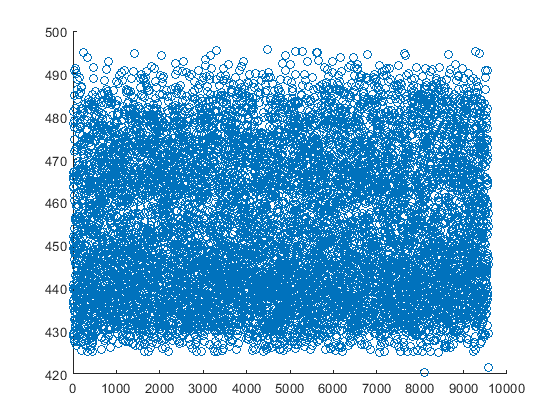


% ScatterPlot
scatter(1:length(W.PE),W.PE)  

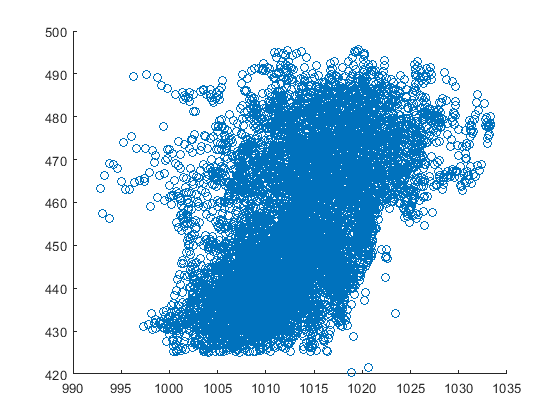

scatter(W.AP,W.PE)

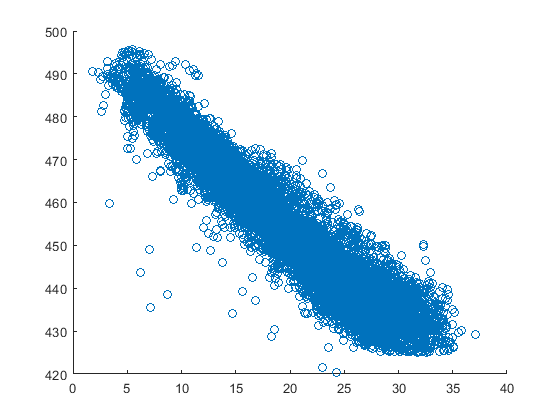

scatter(W.AT,W.PE)

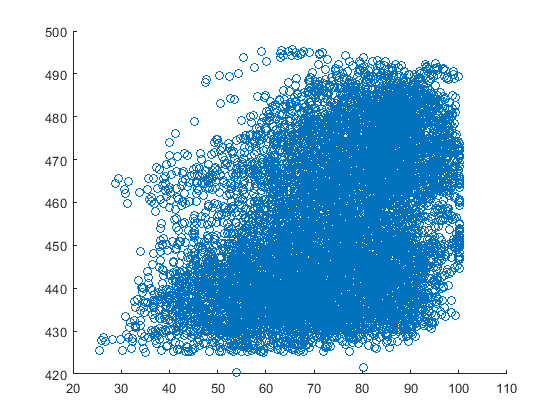

scatter(W.RH,W.PE)

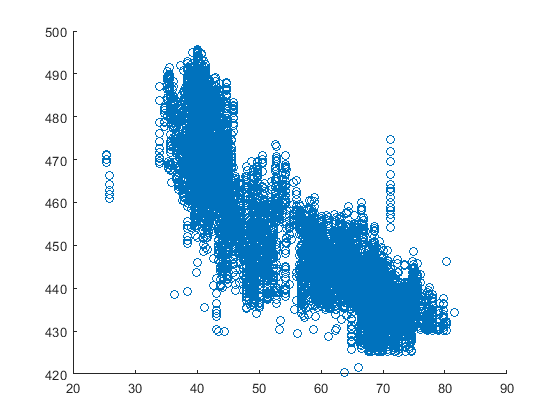

scatter(W.V,W.PE)


x = normalize(1:length(W.PE),'range')

x =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051


data = readtable('PPDataSheet.xlsx');
X = data(:, 1:4);
y = data(:, 5);
m = length(y);

Error using tabular/length (line 189)
Undefined function 'length' for input arguments of type 'table'.  Use the HEIGHT, WIDTH, or SIZE functions instead.